## Lab 9 Problem 1

Eric Nguyen 

format long

**a)** Plot the function $f(x) = \frac{1}{1+12x^2}$ on $[-1,1]$ using 100 evenly spaced points. 

f = @(x) 1 ./ (1 + 12*x.^2);
x = linspace(-1,1,100);
plot(x,f(x));

**b)** Use Vandermonde matrix to approximate the function $f(x) = \frac{1}{1+12x^2}$ using the nodes $x_0 = -1, x_1 = 0, x_2 = 1$. Compute $P_2(x) = a_0 + a_1 x + a_2 x^2$. Use anonymous functions.

x0 = -1;
x1 = 0;
x2 = 1;
V = [1 x0 x0^2
     1 x1 x1^2
     1 x2 x2^2];
y = [f(x0); f(x1); f(x2)];
M = [V y];
a2 = elimination(3,M);
P2 = @(x) a2(1) + a2(2) .* x + a2(3) .* x.^2;

**c)** Plot $P_2(x)$ on the same figure with $f(x)$ using 100 evenly spaced points. Use different colors for the plots.

hold on
plot(x,P2(x));
hold off

**d)** Use the Vandermonde matrix to approximate the same function using the nodes $\{-1,-0.5,0,0.5,1\}$.

x0 = -1;
x1 = -0.5;
x2 = 0;
x3 = 0.5;
x4 = 1;
V = [1 x0 x0^2 x0^3 x0^4
     1 x1 x1^2 x1^3 x1^4
     1 x2 x2^2 x2^3 x2^4
     1 x3 x3^2 x3^3 x3^4
     1 x4 x4^2 x4^3 x4^4];
y = [f(x0); f(x1); f(x2); f(x3); f(x4)];
M = [V y];
a5 = elimination(5,M);
P5 = @(x) a5(1) + a5(2) .* x + a5(3) .* x.^2 + a5(4) .* x.^3 + a5(5) .* x.^4;

**e) **Plot $P_5(x)$ on the same figure with $f(x)$ and $P_2(x)$ using 100 evenly spaced points. Use different colors for the plots. Add a legend. 

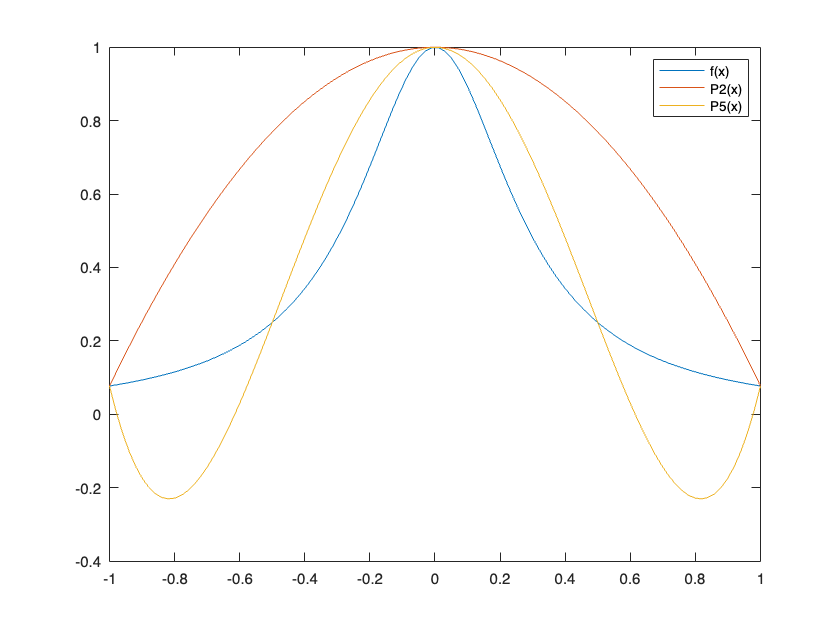

hold on
plot(x,P5(x));
legend('f(x)','P2(x)','P5(x)');
hold off

**f)**  Compute the absolute errors when $P_2$ and $P_4$ are used to approximate $f(0.45)$. *(Do not suppress output)*

P2_err = abs(f(0.45) - P2(0.45))

P2_err =    0.521531733572550


P5_err = abs(f(0.45) - P5(0.45))

P5_err =    0.074318272034088


**Difference from Lagrange interpolant**

There aren't any differences from the Lagrange interpolant in the calculations (the calculations are exactly the same). The Vandermonde matrix approach, however, seems to require many more operations than the Lagrange interpolant approach (and thus take longer).

function x = elimination(n,a)

NROW = zeros(n,1);

for i = 1:n
    NROW(i) = i;
end

for i = 1:n-1
    p = i;
    while abs(a(p,i)) == abs(a(max(i:n),i)) && p < n
        if a(NROW(p),i) == 0
            disp('no unique solution exists');
            return
        end
        if NROW(i) ~= NROW(p)
            NCOPY = NROW(i);
            NROW(i) = NROW(p);
            NROW(p) = NCOPY;
        end

        p = p + 1;
    end

    for j=i+1:n
        m = a(NROW(j),i) / a(NROW(i),i);
        a(NROW(j),:) = a(NROW(j),:) - m*a(NROW(i),:);
    end
end

if a(NROW(n),n) == 0
    disp('no unique solution exists');
    return
end

x(n) = a(NROW(n),n+1) / a(NROW(n),n);

for i = n-1:-1:1
    x(i) = a(NROW(i),n+1);
    for j=i+1:n
        x(i) = x(i) - a(NROW(i),j) * x(j);
    end
    x(i) = x(i) / a(NROW(i),i);
end

end